% Last Modified: 4/2/2024

clc
clear
close all

% Test Settings
annimation = true;
simulation = true;
record_data = false;

% Settting avoid and detection range
r_a = 1;
r_d = 0;
distance = 8;
obs_state = 0;

n = 0;
samples = 1;
apf_pq_r4 = cell(samples,2);
detection_radius = 15;
test_site_size = 15;
% load('Network_pq_r6.mat','net')
if simulation
while n < samples

    %======Comment this section to test use saved initial locations========
    rng('shuffle')
   
    % Generate ally robot: robot2
    robot2 = MbRobot;
    robot2.Start = rand(1,2)*test_site_size;
    robot2.Goal = generateRandomCoords(1, robot2.Start, distance, test_site_size);
    lightColor2 = [0.8 1 0.8 0.2];
    % lightColor2 = [1 1 1 0.2];
    darkColor2 = [0.5 1 0.5 0.2];
    robot2.LightColor = lightColor2;
    robot2.DarkColor = lightColor2;
    robot2.SafeRadius = r_a;
    robot2.HeadAngle = atan2(robot2.Goal(2) - robot2.Start(2), ...
                                robot2.Goal(1) - robot2.Start(1));
    robot2.CurrentPose = [robot2.Start'; robot2.HeadAngle; robot2.AngularVelocity];
    robot2.CurrentCoord = robot2.CurrentPose(1:2);
    robot2.DetectionRadius = detection_radius;
    

    robot3 = MbRobot;
    [robot3.Start, robot3.Goal, interceptPoint] = generateInterceptingPath(robot2.Start, robot2.Goal, ...
        test_site_size, distance);

    lightColor3 = [0.6 0.8 1 0.2];
    % lightColor3 = [1 1 1 0.2];
    darkColor3 = [0.4 0.6 1 0.2];
    robot3.LightColor = lightColor3;
    robot3.DarkColor = lightColor3;
    robot3.SafeRadius = r_a;
    robot3InitPose = robot3.CurrentPose;
    robot3.HeadAngle = atan2(robot3.Goal(2) - robot3.Start(2), ...
                                robot3.Goal(1) - robot3.Start(1));
    robot3.CurrentPose = [robot3.Start'; robot3.HeadAngle; robot3.AngularVelocity];
    robot3.CurrentCoord = robot3.CurrentPose(1:2);
    robot3.DetectionRadius = detection_radius;
    % Generate ego robot, robot1
    existCoords = [robot2.Start; robot2.Goal; robot3.Start; robot3.Goal];

    %==============================================================================
   

    % estm_poses3 = [];
    poses2 = [];
    poses3 = [];

    % Define sample time, and simulation time
    sampleTime = 0.1;
    simulationTime = 30;
    
  


     % Simulation Loop
    for t = 0:sampleTime:simulationTime

        % robot1Pose = robot1.CurrentPose;
        robot2Pose = robot2.CurrentPose;
        robot3Pose = robot3.CurrentPose;


        % For ally robot and enemy robot
        % [obstacleInAvoidRange2, obstaclePose] = ...
        %         obstacleDetection(robot2Pose, robot3Pose(1:2,:), robot2.SafeRadius);
        % obstacleInAvoidRange3 = obstacleInAvoidRange2;
        obstaclePose2 = [robot3Pose(1:2,:)];
        obstaclePose3 = [robot2Pose(1:2,:)];
        robot2.Obstacle = obstaclePose2;
        robot2.artificial_potential_field(sampleTime,1,1);

        robot3.Obstacle = obstaclePose3;
        robot3.artificial_potential_field(sampleTime,1,1.2);
        if robot2.atGoal() || robot3.atGoal()
            break;
        end
     

        %% To predict the location of obstacles
        % if recordCount < recordSize
        %     robot2PoseData(: , recordCount+1) = robot2.CurrentPose;
        %     recordCount = recordCount + 1;
        % else
        %     robot2PoseData(:,bufferSize:end-bufferSize) = ...
        %         robot2PoseData(:,1+bufferSize:end);
        %     robot2PoseData(:,end) = robot2.CurrentPose;
        %     inputs = [robot3InitPose,robot2PoseData];
        %     % estmRobot3 = predict(net,{inputs});
        %     % estm_poses3 = [estm_poses3, [estmRobot3(1);estmRobot3(2)]];
        % end


     
        % % For ego robot
        % [obstacleInAvoidRange1, obstacleInDetectionRange1, obstaclePose] = ...
        %     obstacleDetection(robot1Pose, [robot2Pose; robot3Pose], ...
        %     robot1.SafeRadius, robot1.DetectionRadius);
        % if obstacleInAvoidRange1
        %     robot1.rotate(sampleTime, pi/4);
        % else
        %     robot1.goStraight(sampleTime,robot1.Goal);
        % end


        poses2 = [poses2, robot2.CurrentPose];
        poses3 = [poses3, robot3.CurrentPose];
    

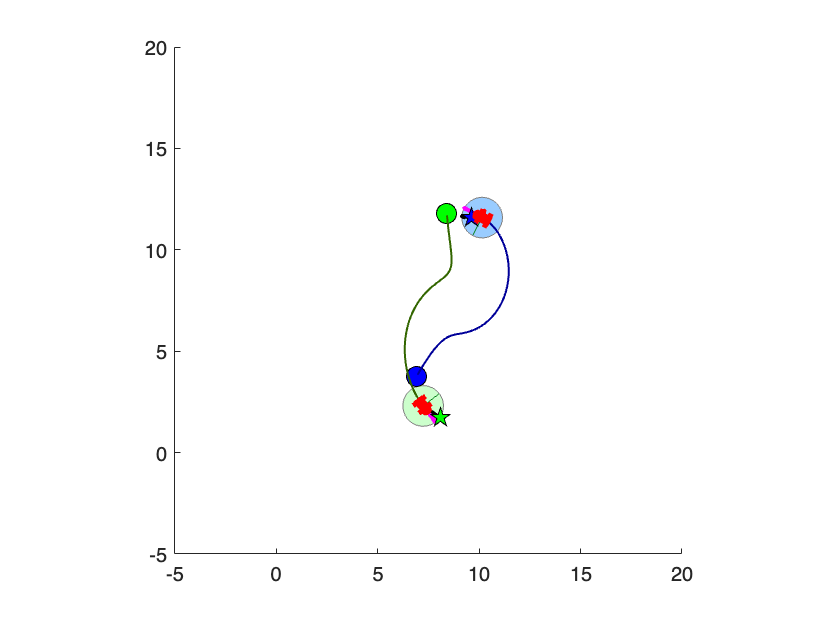

        if annimation
            % Plot the robot's position
            figure(1)
            set(gcf,'DoubleBuffer','off','Renderer','opengl')
            clf; % clear current figure
            robot2.plotRobot(1); % adjust the frame size as needed
            robot3.plotRobot(1);
            % robot1.plotRobot(1);
    
            hold on
            plot(robot2.Start(1),robot2.Start(2),'ko','MarkerSize',10,'MarkerFaceColor','g')
            plot(robot2.Goal(1),robot2.Goal(2),'kp','MarkerSize',10,'MarkerFaceColor','g')
            
            plot(robot3.Start(1),robot3.Start(2),'ko','MarkerSize',10,'MarkerFaceColor','b')
            plot(robot3.Goal(1),robot3.Goal(2),'kp','MarkerSize',10,'MarkerFaceColor','b')
            plot(poses2(1,:),poses2(2,:),'-',...
                'Color',[51,102,0]/255,'LineWidth',1);   % Orange: [1 0.5 0]
            plot(poses3(1,:),poses3(2,:),'-',...
                'Color',[0,0,153]/255,'LineWidth',1);
            % try
            %     plot(estm_poses3(1,:),estm_poses3(2,:),'-',...
            %         'Color',[0 0 1],'LineWidth',1)
            % catch ME
            %     fprintf(ME.message,'\n');
            % end
            axis equal;
            xlim([-5, 20]);
            ylim([-5, 20]);
            drawnow
        end
    end

%     if ~robot2.atGoal()
%         disp('Robot did not reach the goal within the simulation time.');
%     end
    
    n = n + 1;
    apf_pq_r4{n,1} = poses2;
    apf_pq_r4{n,2} = poses3;
    % allWaypoints_pq_r2{n,3} = estm_poses3;
    if mod(n, 1000) == 0
        fprintf('Completed Trials: %d\n', n);
    end
end
end

    
if record_data
    save("Data/SimulationData/strict_apf_ally_turn.mat","apf_pq_r4")
end% Plot the results for 1 simulation for future use


load('Data/SimulationData/strict_apf_ally_turn.mat','apf_pq_r4')

Error using load
Unable to find file or directory 'Data/SimulationData/strict_apf_ally_turn.mat'.

plotSample = 4000;
poses2 = apf_pq_r4{plotSample,1};
poses3 = apf_pq_r4{plotSample,2};
robot2 = MbRobot;
robot3 = MbRobot;

robot2.CurrentPose = poses2(1:4,end);
robot3.CurrentPose = poses3(1:4,end);
robot2.Start = poses2(1:2,1);
robot3.Start = poses3(1:2,1);
robot3.Goal = poses2(1:2,end);
robot3.Goal = poses3(1:2, end);
figure;
plot(poses2(1,:),poses2(2,:),'-',...
                'Color',[0,1,0],'LineWidth',1);   % Orange: [1 0.5 0]
hold on
plot(poses3(1,:),poses3(2,:),'-',...
                'Color',[0,0,1],'LineWidth',1);
plot(robot2.Start(1),robot2.Start(2),'ko','MarkerSize',10,'MarkerFaceColor','g')
plot(robot2.Goal(1),robot2.Goal(2),'kp','MarkerSize',10,'MarkerFaceColor','g')

plot(robot3.Start(1),robot3.Start(2),'ko','MarkerSize',10,'MarkerFaceColor','b')
plot(robot3.Goal(1),robot3.Goal(2),'kp','MarkerSize',10,'MarkerFaceColor','b')

x = [6 6 6 6];
y = [6 6 6 6];
color_b = [155/255, 203/255, 251/255];
color_g = [203/255, 251/255. 203/255];
fill(x,y,color_g)
fill(x,y,color_b)

legend('Ally Trajectory', 'Obstacle Trajectory','Ally Start Point','Ally Goal',...
    'Obstacle Start Point', 'Obstacle Goal', 'Ally Detection Range', 'Obstacle Detection Range')
axis equal;
xlim([-5, 20]);
ylim([-5, 20]);
